---------------------------------------------------------------------------

copyright@ Xiaoxing Hu Email:72744505@qq.com 

modifide history: 2022/5/28

version:1.0

exp: 实验1，探究不同样本库大小对实验的影响

---------------------------------------------------------------------------

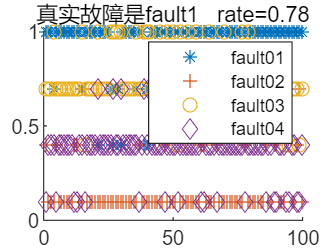

N1 = 100; %数据库大小
N2 = 100; %样本测试数量
score = [1 ,0.7, 0.4, 0.1];
weight = [1,0.8,0.1,0.08];%权重系数
rate = 0;%正确率
scorex = zeros(4,N2);%存放得分数据
timeflag = 1000;%时间戳
test_type = 1;%测试故障为序号
%------------------------------------------------------------------------------
[S1,Omega_fault1] = make_Omega(fault1_input(timeflag-N1+1:timeflag,:)',fault1_output(timeflag-N1+1:timeflag,:)');
[S2,Omega_fault2] = make_Omega(fault2_input(timeflag-N1+1:timeflag,:)',fault2_output(timeflag-N1+1:timeflag,:)');
[S3,Omega_fault3] = make_Omega(fault3_input(timeflag-N1+1:timeflag,:)',fault3_output(timeflag-N1+1:timeflag,:)');
[S4,Omega_fault4] = make_Omega(fault4_input(timeflag-N1+1:timeflag,:)',fault4_output(timeflag-N1+1:timeflag,:)');
Omega = [Omega_fault1,Omega_fault2,Omega_fault3,Omega_fault4];%4x32
for j = timeflag+1:timeflag+N2 %1001:1100
    data_all = [fault1_input(j,:),fault1_output(j,:);fault2_input(j,:),fault2_output(j,:);fault3_input(j,:),fault3_output(j,:);fault4_input(j,:),fault4_output(j,:)];
    %data:4x8
    data_test = data_all(test_type,:)';
    sum = zeros(1,4);%计算残差的大小
    vec = zeros(4,4);%行数表示残差的深度，列数表示Omega的种类
    for k = 1:4 %4个Omega
        vectemp = Omega(:,8*k-7:8*k) * data_test;
        vec(:,k) = vectemp;%4x4每一列代表一个Omega得到的残差
    end
    for k = 1:4
        for l = 1:4%计算残差的个数 s =2
           sum(k) = sum(k) + weight(l)*abs(vec(l,k));
        end
    end
    [sorted_sum,~] = sort(sum);
    scorex(1,j-timeflag) =  score(find(sorted_sum==sum(1)));
    scorex(2,j-timeflag) =  score(find(sorted_sum==sum(2)));
    scorex(3,j-timeflag) =  score(find(sorted_sum==sum(3)));
    scorex(4,j-timeflag) =  score(find(sorted_sum==sum(4)));
end
for m=1:N2
    if(scorex(test_type,m)==1)
        rate=rate+1;
    end
end
myplot1(scorex,rate,test_type)